# Matpower Simulation - 6 bus grid

Matpower is an open source simulation engine and optimal power flow calculator for MATLAB. More info here: [https://matpower.org/.](https://matpower.org/.)

We want to use it to simulate the behaviour of our identification algorithm on real networks.

## Network definition

We choose a standard testbed. 

clear all
close all
clc
rng(11);

We load the data and we define the simulation setup to be used.

define_constants;
samples = 2000;
noise_v_sd = 0;
noise_i_sd = 0;
random_load_power_cv = 0.1;
mpc = loadcase('case14');

We define useful constants and we derive the impedence matrix.

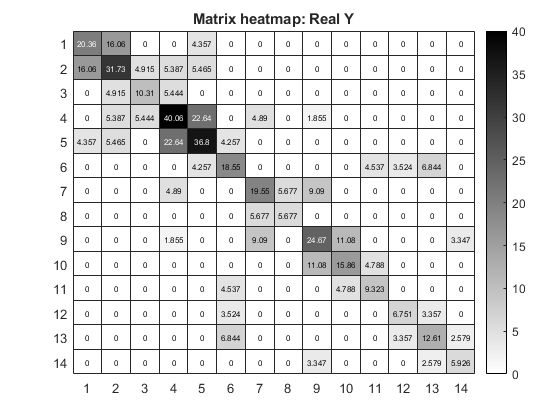

Y = full(makeYbus(mpc));
load_mask = mpc.bus(:, BUS_TYPE) == PQ;
controllable_mask = mpc.bus(:, BUS_TYPE) == PV;
n = size(mpc.bus, 1);
n_gen = size(mpc.gen, 1);
n_controllable = sum(controllable_mask);
n_load = n - n_gen;
matrix_heatmap(Y, 'Real Y');

We check that the admittance matrix is in fact Laplacian.

max(sum(Y, 2))

ans = 0.0000 + 0.2895i

issymmetric(Y)

ans = logical
   1


Looks like it is, in fact!

## Grid simulation

We choose an arbitrary number of time steps and we simulate the evolution of the grid over those instants. 

At the moment, active and reactive power requirements for loads are random, but we will shortly move towards real profiles.

load_avg_pd = mpc.bus(load_mask, PD);
load_avg_qd = mpc.bus(load_mask, QD);
for i = 1:samples
    mpc.bus(load_mask, PD) = normrnd(load_avg_pd, random_load_power_cv * abs(load_avg_pd));
    mpc.bus(load_mask, QD) = normrnd(load_avg_qd, random_load_power_cv * abs(load_avg_qd));
    res = runpf(mpc);
    bus_phase = res.bus(:, VA) * pi / 180;
    bus_magnitude = res.bus(:, VM);
    bus_voltage(:, i) = bus_magnitude .* (cos(bus_phase) + sqrt(-1) * sin(bus_phase));
    load_pd(:, i) = res.bus(load_mask, PD);
    load_qd(:, i) = res.bus(load_mask, QD);
end


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 2 iterations.

Converged in 0.11 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses             14     Total Gen Capacity     772.4         -52.0 to 148.0
Generators         5     On-line Capacity       772.4         -52.0 to 148.0
Committed Gens     5     Generation (actual)    271.8              84.1
Loads             11     Load                   258.4              74.6
  Fixed           11       Fixed                258.4              74.6
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

ev = normrnd(0, noise_v_sd, size(bus_voltage));
ei = normrnd(0, noise_i_sd, size(bus_voltage));
bus_current = Y * bus_voltage + ei;
bus_voltage = bus_voltage + ev;

Randomly generated voltages and currents for testing purpose only.

% bus_voltage = normrnd(100, 5, [n, samples]) + sqrt(-1) * normrnd(100, 5, [n, samples]);
% bus_current = Y * bus_voltage;

We visualize the evolution of the voltage and the current for a random node.

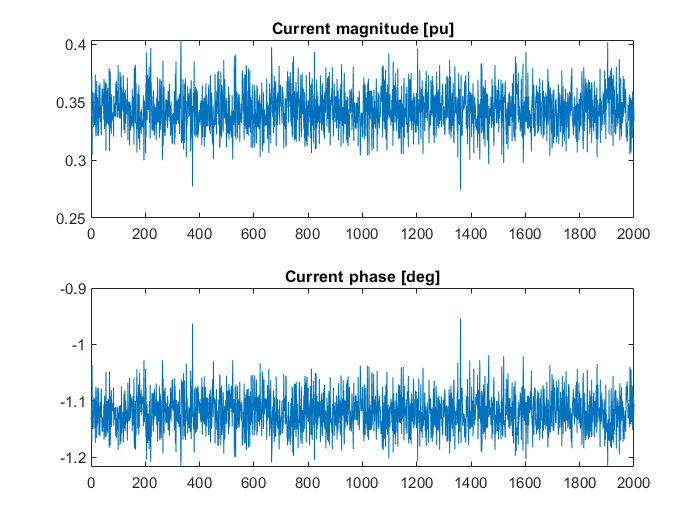

viz_node = 2;
viz_current = bus_current(viz_node, :);
viz_voltage = bus_voltage(viz_node, :);

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_current));
title('Current magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_current));
title('Current phase [deg]');

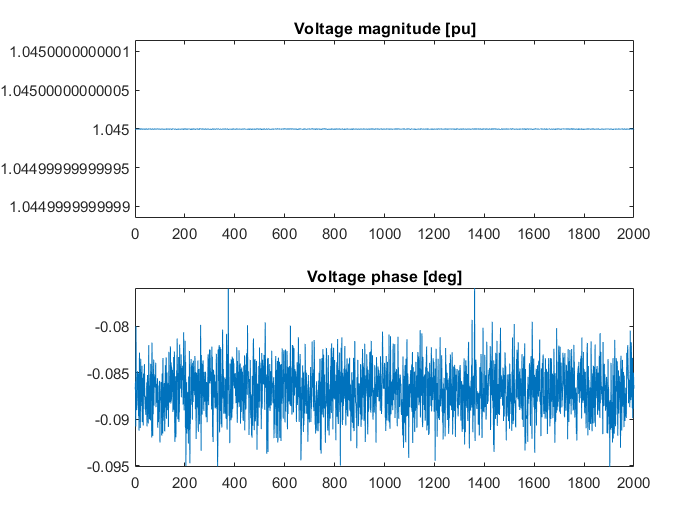

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_voltage));
title('Voltage magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_voltage));
title('Voltage phase [deg]');

Moreover, we check correlation between voltages

corr(bus_voltage')

ans =    1.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 - 0.0000i   1.0000 + 0.0000i   0.9907 + 0.1346i   0.9612 + 0.2674i   0.9683 + 0.2387i   0.9214 + 0.1498i   0.9235 + 0.2156i   0.9446 + 0.1389i   0.8686 + 0.2329i   0.8727 + 0.2293i   0.9018 + 0.1998i   0.8888 + 0.1800i   0.8772 + 0.2000i   0.8262 + 0.2489i
  -0.0000 + 0.0000i   0.9907 - 0.1346i   1.0000 + 0.0000i   0.9888 + 0.1356i   0.9904 + 0.1058i   0.9272 + 0.0242i   0.9406 + 0.0894i   0.9511 + 0.0104i   0.8873 + 0.1139i   0.8906 + 0.1097i   0.9149 + 0.0764i   0.8981 + 0.0578i   0.8890 + 0.0788i   0.8456 + 0.1341i
   0.0000 - 0.0000i   0.9612 - 0.2674i   0.9888 - 0.1356i   1.0000 + 0.0000i   0.9959 - 0.0310i   0.9150 - 0.1088i   0.9447 - 0.0474i   0.9381 - 0.1246i   0.8983 - 0.0196i   0.9003 - 0.0237i   

## Error metrics

We define the error metrics we are going to use to test the accuracy of the estimation algorithms. Define the error matrix $Y_e = \left |Y - \hat Y \right|$. We are going to use the following error metrics:

- Frobenius norm of $Y_e$

- Max norm of $Y_e$

Moreover, we will resort to an heatmap to see how the absoulte error in the estimation of the admittance matrix is distributed among the different elements.

## OLS estimation

As a first benchmark, we estimate the admittance matrix using Ordinary Least.

Froebius norm for OLS is 6.434e-05
Max norm for OLS is 3.8176e-05


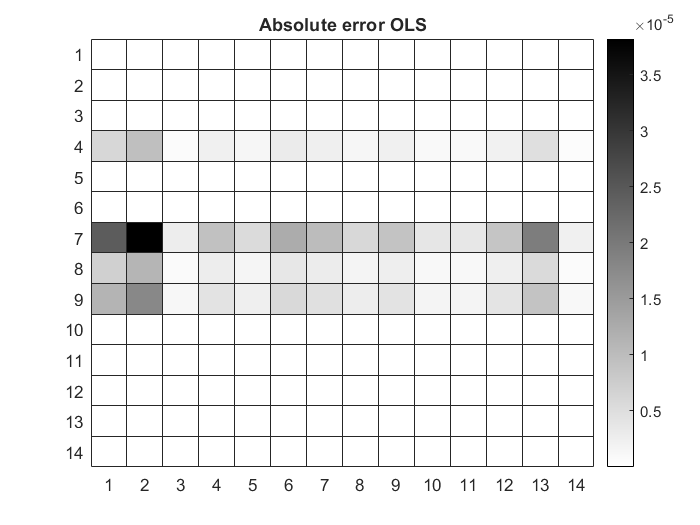

Y_hat_ols = conj(bus_voltage' \ bus_current');
error_metrics(Y, Y_hat_ols, 'OLS');

## Lasso Estimation

Following Ardakanian et al, we now resort to Lasso in order to peform the same estimation.

idx = 1:n;
nidx = setdiff(1:n,idx);
[Y22_est, Y12_est, Y11_est] = postprocessing(bus_voltage,bus_current,idx,nidx,Y);

Lasso method is being used...
best lambda is 0.0001
maximum absolute error is 7.1474e-05
error norm is 0.00048995
no. nonzero elements: 54
Thresholded lasso method with refitting is being used...
best lambda is 0.0001
maximum absolute error is 1.0076e-05
error norm is 1.9946e-05
no. nonzero elements: 54
Adaptive lasso method with OLS based weights is being used...
optimal gamma is 2
best lambda is 0.0001
maximum absolute error is 4.689e-05
error norm is 0.00012588
no. nonzero elements: 54
Thresholded lasso with refitting outperformed other methods
Relative error (pct): 0.0001226


Froebius norm for Lasso is 1.9946e-05
Max norm for Lasso is 1.0076e-05


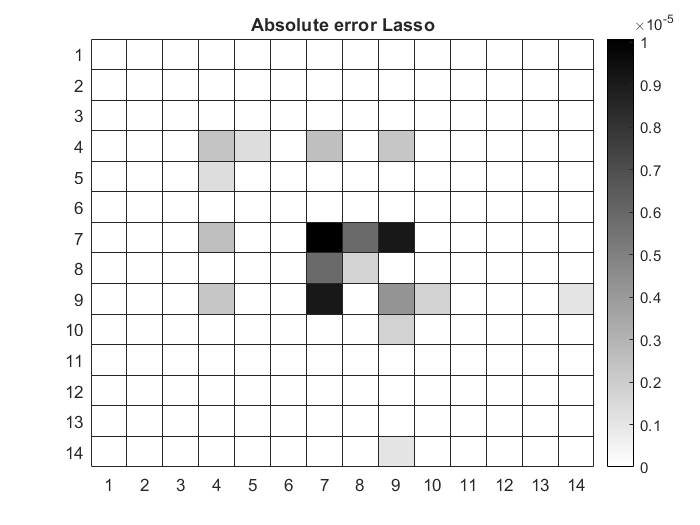

Y_hat_lasso  = [Y11_est Y12_est; Y12_est.' Y22_est];
error_metrics(Y, Y_hat_lasso, 'Lasso');

## RLS with symmetricity constraints (RLS1)

We implement a recursive least square (RLS) estimator for $Y$, with a forgetting factor $\lambda$. However, we do not take into account the structure of the admittance matrix. Thus, the Laplacian is not assured to be symmetric nor to have a zero-row sum and the number of paramters to estimate is $n^2$, where $n$ is the number of nodes (generator and loads) in the network. Arbitrary initial guesses for both the admittance matrix and the variance of its parameters must be provided. 

lambda = 0.95;
D = duplication_matrix(n);
Y1_hat = estimate_rls(bus_voltage, bus_current, D, lambda);

Completed iteration 100
Completed iteration 200
Completed iteration 300
Completed iteration 400
Completed iteration 500
Completed iteration 600
Completed iteration 700
Completed iteration 800
Completed iteration 900
Completed iteration 1000
Completed iteration 1100
Completed iteration 1200
Completed iteration 1300
Completed iteration 1400
Completed iteration 1500
Completed iteration 1600
Completed iteration 1700
Completed iteration 1800
Completed iteration 1900
Completed iteration 2000


Froebius norm for RLS1 is NaN
Max norm for RLS1 is NaN


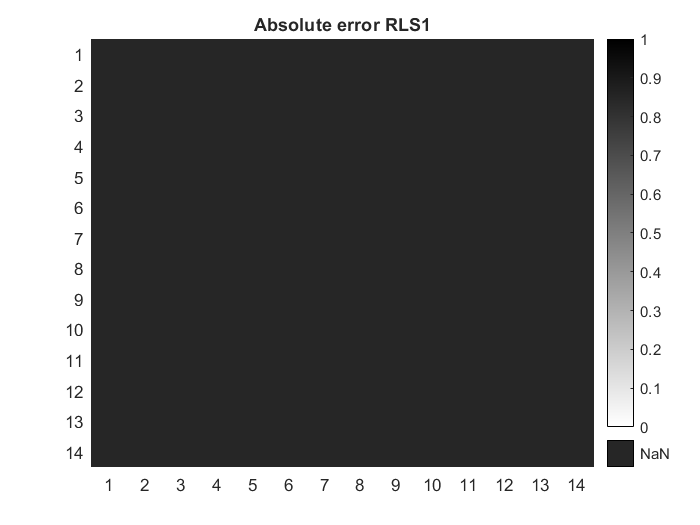

error_metrics(Y, Y1_hat(:, :, end), 'RLS1');

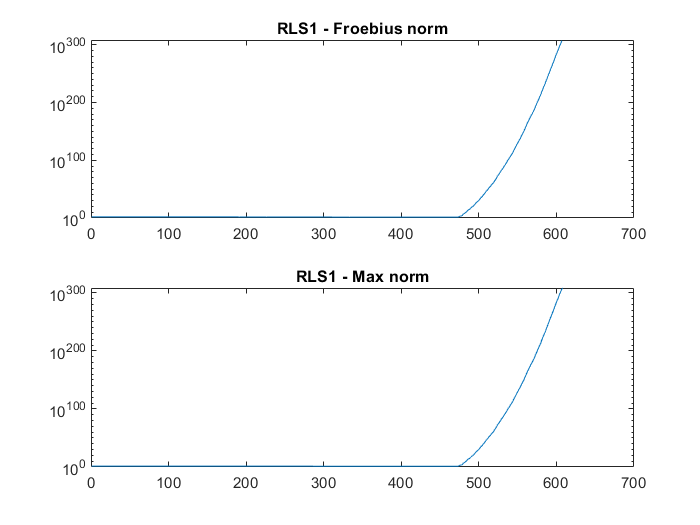

[rls1_foeb, rls1_max] = error_evolution(Y, Y1_hat, 'RLS1');

## RLS2

Then, we implement a similar RLS algorithm which takes into account the constraints on the Laplacian admittance matrix and thus reduces the number of free parameters from to $n(n-1)/2$.

Q = D * transformation_matrix(n);
Y2_hat = estimate_rls(bus_voltage, bus_current, Q, lambda);

Completed iteration 100
Completed iteration 200
Completed iteration 300
Completed iteration 400
Completed iteration 500
Completed iteration 600
Completed iteration 700
Completed iteration 800
Completed iteration 900
Completed iteration 1000
Completed iteration 1100
Completed iteration 1200
Completed iteration 1300
Completed iteration 1400
Completed iteration 1500
Completed iteration 1600
Completed iteration 1700
Completed iteration 1800
Completed iteration 1900
Completed iteration 2000


Froebius norm for RLS2 is 10.7588
Max norm for RLS2 is 5.1638


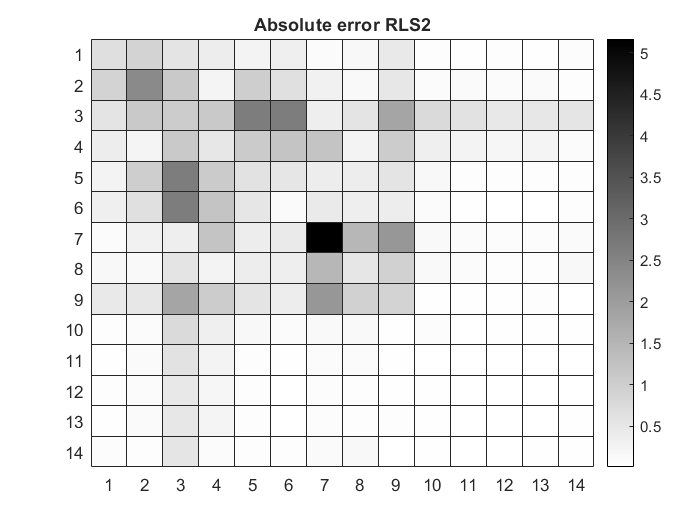

error_metrics(Y, Y2_hat(:, :, end), 'RLS2');

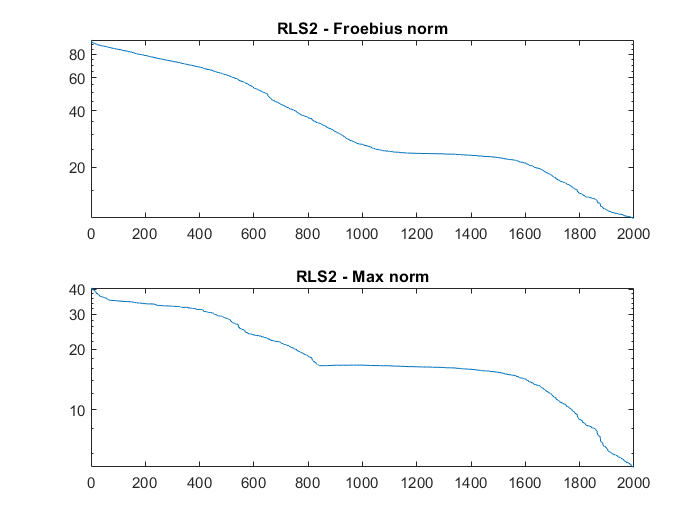

[rls2_foeb, rls2_max] = error_evolution(Y, Y2_hat, 'RLS2');

## RLS with DoE

Finally, we integrate Design of Experiment into our framework

x0_doe = 0.1 * ones([size(Q, 2) 1]);
Z0_doe = 100 * eye(size(Q, 2));
[Y_hat_doe, x_hat_doe, Z_doe, V_real_doe] = estimate_rls_doe(load_pd, load_qd, load_mask, controllable_mask, ev, ei, mpc, Q, lambda, Y, x0_doe, Z0_doe);

Difference between estimated and reconstruced matrix 0

MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.523649e+01     1.219e+00     1.000e+00     0.000e+00     4.563e+01  
    1          38    6.104608e+01     1.034e+00     1.000e+00     2.823e+00     9.126e+03  
    2          60    6.219177e+01     1.003e+00     3.430e-01     3.579e+00     9.126e+03  
    3          83    6.248164e+01     9.155e-01     2.401e-01     1.021e+00     9.126e+03  
    4         105    6.197913e+01     9.853e-01     3.430e-01     1.030e+00     9.126e+03  
    5         128    6.175124e+01     9.578e-01     2.401e-01     9.006e-01     9.126e+03  
    6         152    6.163096e+01     9.054e-01     1.681e-01     5.567e-01     9.126e+03  
  

Froebius norm for DoE is 0.015943
Max norm for DoE is 0.0073327


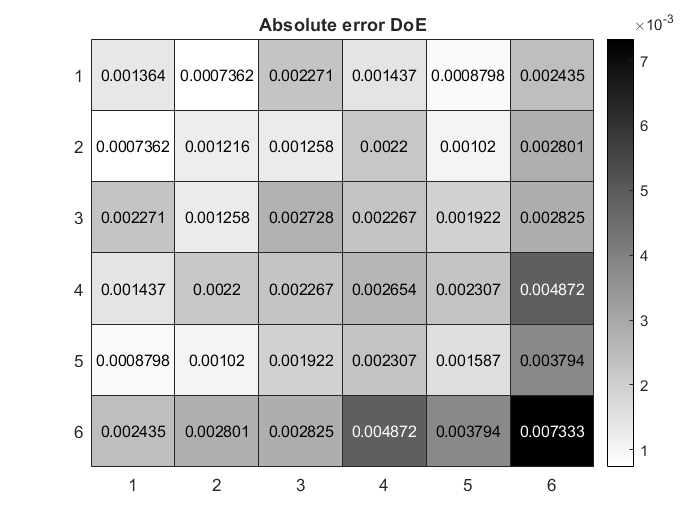

error_metrics(Y, Y_hat_doe(:, :, end), 'DoE');

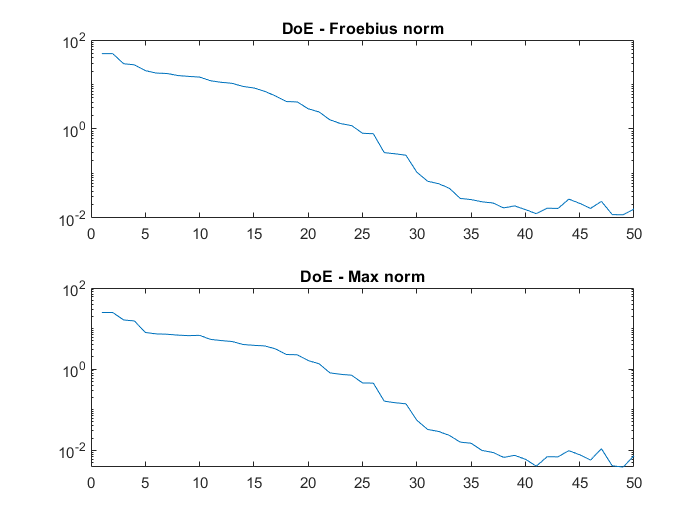

[doe_foeb, doe_max] = error_evolution(Y, Y_hat_doe, 'DoE');

We also investigate voltage evolution.

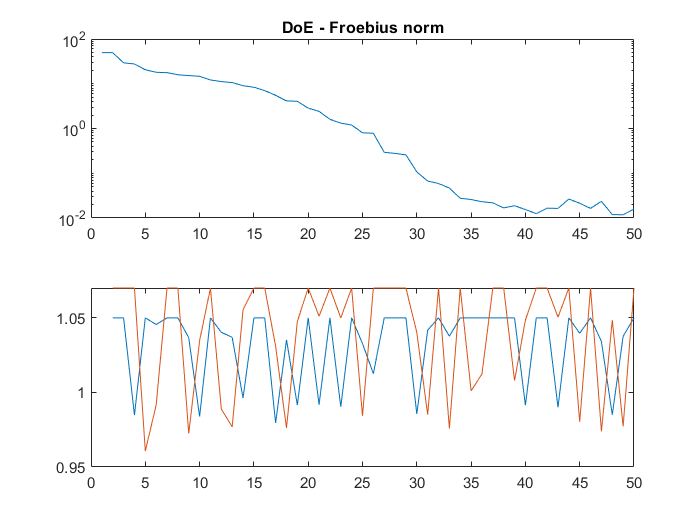

plot(2:samples, abs(V_real_doe(2:3, 2:end)));

## Comparison between methods

Finally, we compare error evolution between the two methods

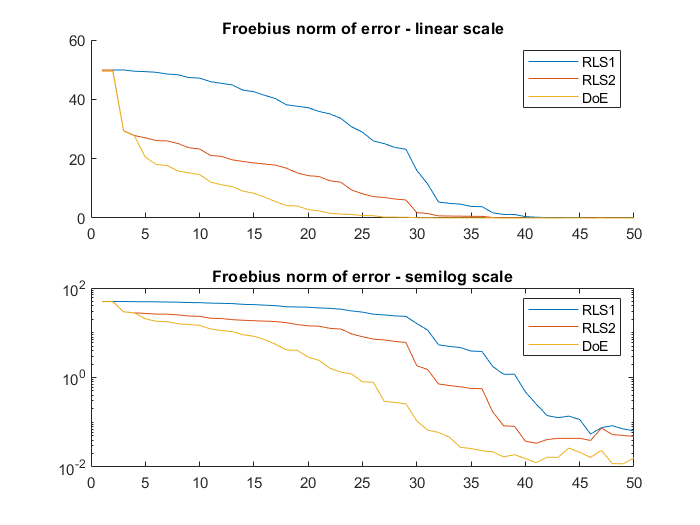

figure()
subplot(2, 1, 1)
hold on
plot(1:samples, rls1_foeb);
plot(1:samples, rls2_foeb);
plot(1:samples, doe_foeb);
hold off
legend('RLS1', 'RLS2', 'DoE');
title('Froebius norm of error - linear scale');
subplot(2, 1, 2)
semilogy([rls1_foeb; rls2_foeb; doe_foeb]');
legend('RLS1', 'RLS2', 'DoE');
title('Froebius norm of error - semilog scale');

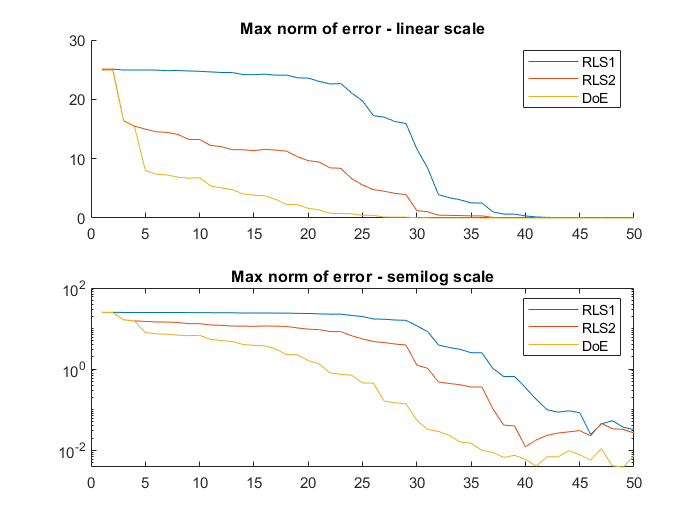

figure()
subplot(2, 1, 1)
hold on
plot(1:samples, rls1_max);
plot(1:samples, rls2_max);
plot(1:samples, doe_max);
hold off
legend('RLS1', 'RLS2', 'DoE');
title('Max norm of error - linear scale');
subplot(2, 1, 2)
semilogy([rls1_max; rls2_max; doe_max]');
legend('RLS1', 'RLS2', 'DoE');
title('Max norm of error - semilog scale');

## Export data for figures

froe_errors_without_fault = [rls1_foeb; rls2_foeb; doe_foeb]';
max_errors_without_fault = [rls1_max; rls2_max; doe_max]';
writematrix(froe_errors_without_fault, 'froe_errors_without_fault.csv');
writematrix(max_errors_without_fault, 'max_errors_without_fault.csv');
writematrix(abs(V_real_doe)', 'doe_voltages_without_fault.csv');